# **Signal and Systems**

## **Experiment No. # 13**

### Objective: 

The objective of this lab is to learn how to implement the basic types of filters in MATLAB  and to apply them on an audio signal. 

### Theoretical Background:

#### Filters: 

Filters, in general, are used to block some part of a signal and to pass some particular part of  a signal. In frequency domain, we say that a filter will block a certain range of frequencies,  while passing a specific range of frequencies. The three most common types of filters are: 

1. Low pass Filters (LPF) 

2. Band pass Filters (BPF)

 3. High pass Filters (HPF) 

#### 1. Low Pass Filter: 

A low pass filter, as its name suggests, is used to pass only the low frequency components of  a signal, and block all higher frequency components. 

#### 2. Band Pass Filter: 

A band pass filter is a filter that passes all frequencies of a signal within a certain range,  (which neither includes zero frequency nor pi), and block all other frequencies outside that  range. 

#### 3. High Pass Filter: 

A high pass filter is used to pass all frequency components of a signal higher than a cutoff  frequency, and stop all other frequency components which are lower than the cutoff  frequency. 

#### Tasks: 

In order to create an understanding of passing signals through filters, the following tasks are  to be performed by the students: 

#### Task 1: 

Using the filter design toolbox, (FDA tool), design three filters with the following  specifications: 

a) A Low Pass Filter with pass band (f < 1500 Hz) 

b) A Band Pass Filter with pass band (1500 < f < 3000 Hz) 

c) A High Pass Filter with pass band (f > 3000 Hz) 

#### Task 2: 

• Using audiorecorder, record a 5 second audio in MATLAB 

• Export the filters into workspace, and save the filters and recorder object in a ‘.mat’ file. 

• In a new MATLAB script, load the ‘.mat’ file into workspace. Now pass the signal  through each of the three filters separately. 

• Reconstruct the original signal by adding the outputs of all three filters 

• Using subplot, show the original signal, the outputs of the three filters, and then the  reconstructed signal. 

#### Task 1: 

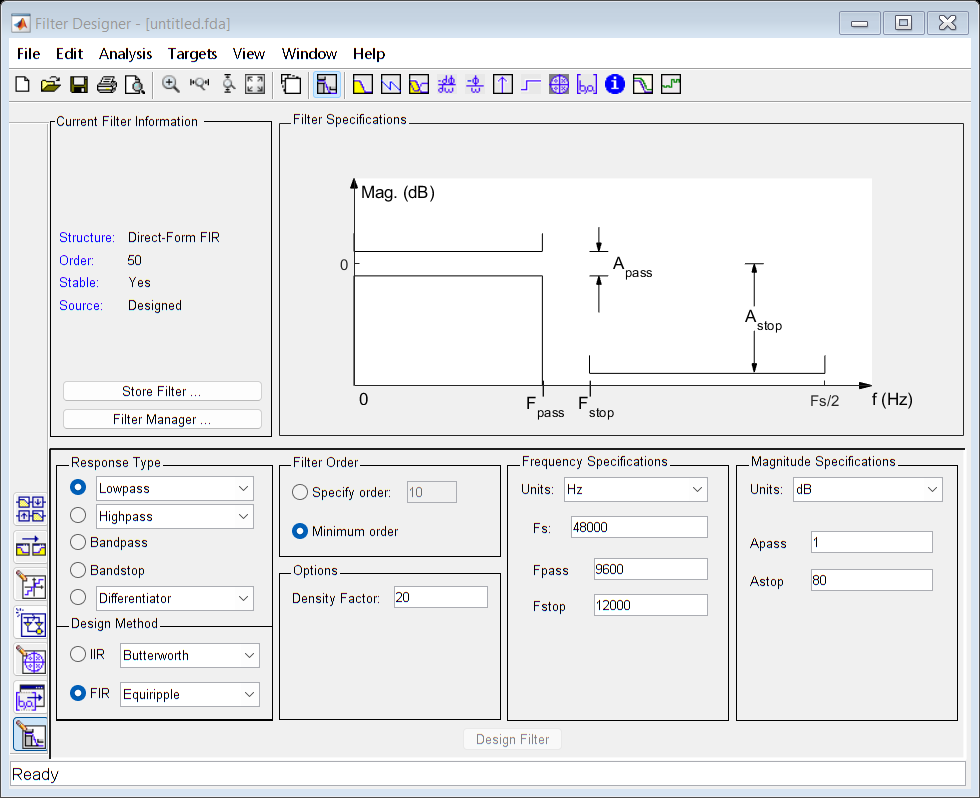

filterDesigner;

#### Task 2: 

% Create an audiorecorder object
recObj = audiorecorder;

% Record 5 seconds of audio
disp('Start speaking.');

Start speaking.


recordblocking(recObj, 2);
disp('End of Recording.');

End of Recording.


% Save the recorded audio to a variable
audioData = getaudiodata(recObj);

% Save the filters and recorder object in a MAT file
save('audio_processing_data.mat', 'LPF', 'BPF', 'HPF', 'recObj');

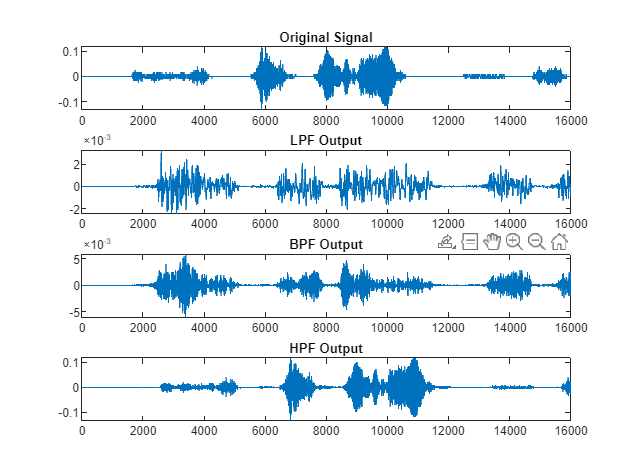

% Load the MAT file into the workspace
load('audio_processing_data.mat');

% Pass the signal through each filter separately
outputLPF = filter(LPF, audioData);
outputBPF = filter(BPF, audioData);
outputHPF = filter(HPF, audioData);

% Reconstruct the original signal by adding the outputs of all three filters
reconstructedSignal = outputLPF + outputBPF + outputHPF;

% Plot the signals using subplot
figure;

% Original Signal
subplot(4,1,1);
plot(audioData);
title('Original Signal');

% Filtered Signals
subplot(4,1,2);
plot(outputLPF);
title('LPF Output');

subplot(4,1,3);
plot(outputBPF);
title('BPF Output');

subplot(4,1,4);
plot(outputHPF);
title('HPF Output');

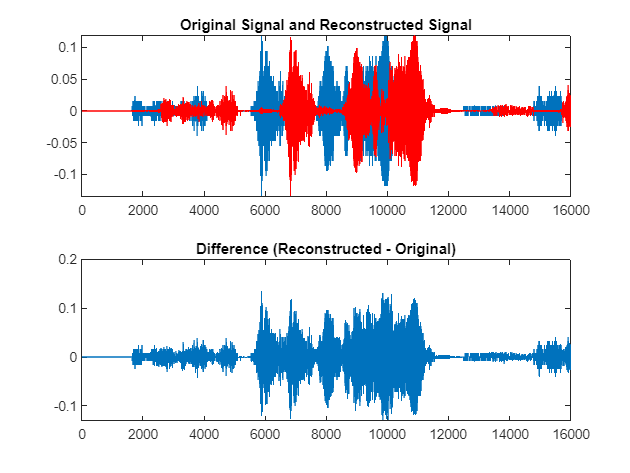

% Reconstructed Signal
figure;
subplot(2,1,1);
plot(audioData);
hold on;
plot(reconstructedSignal, 'r');
title('Original Signal and Reconstructed Signal');

subplot(2,1,2);
plot(reconstructedSignal - audioData);
title('Difference (Reconstructed - Original)');